# Introduction to surface based analyses

figure; set(gcf,'Visible','on')
srfwhite = loadsrf('fs5', 'white')

srfwhite = struct with fields:
    lh: [1×1 struct]
    rh: [1×1 struct]

srfpial = loadsrf('fs5', 'pial')

srfpial = struct with fields:
    lh: [1×1 struct]
    rh: [1×1 struct]

srfinflated = loadsrf('fs5', 'inflated')

srfinflated = struct with fields:
    lh: [1×1 struct]
    rh: [1×1 struct]

srfsphere = loadsrf('fs5', 'sphere')
subplot(1,2,1)
srfplot(srfwhite.lh)

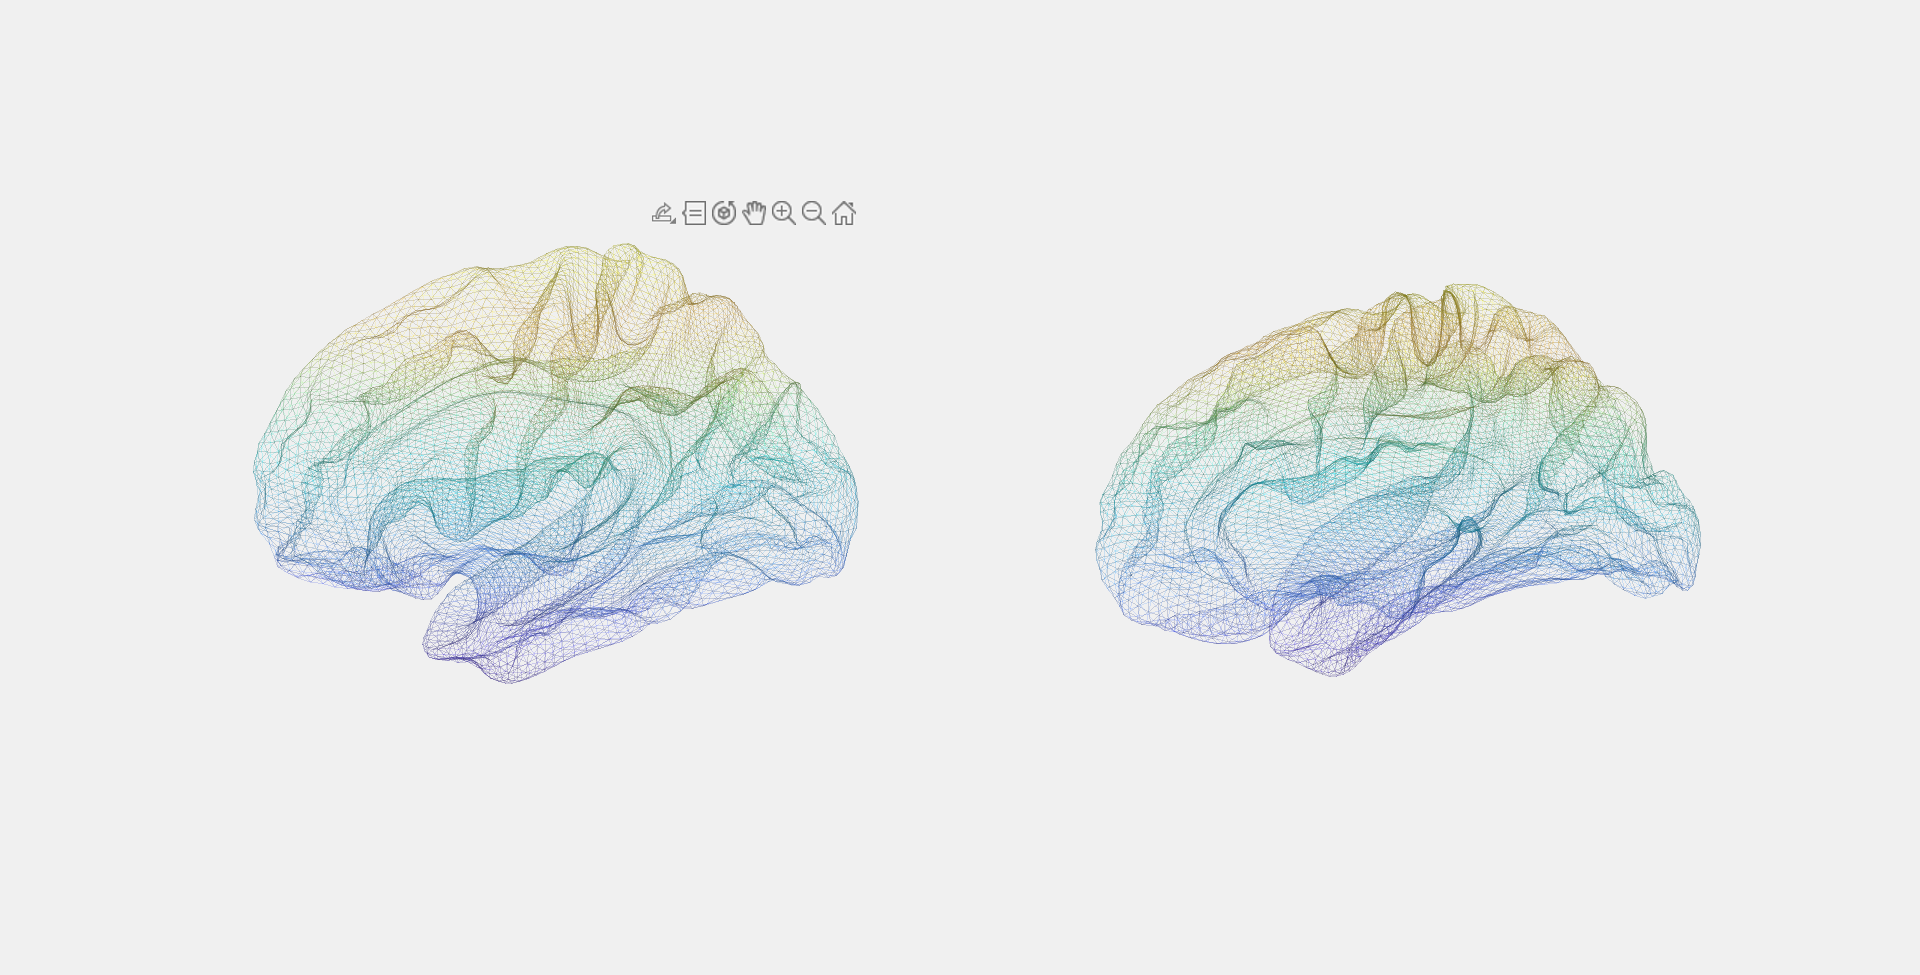

subplot(1,2,2)
srfplot(srfwhite.rh)

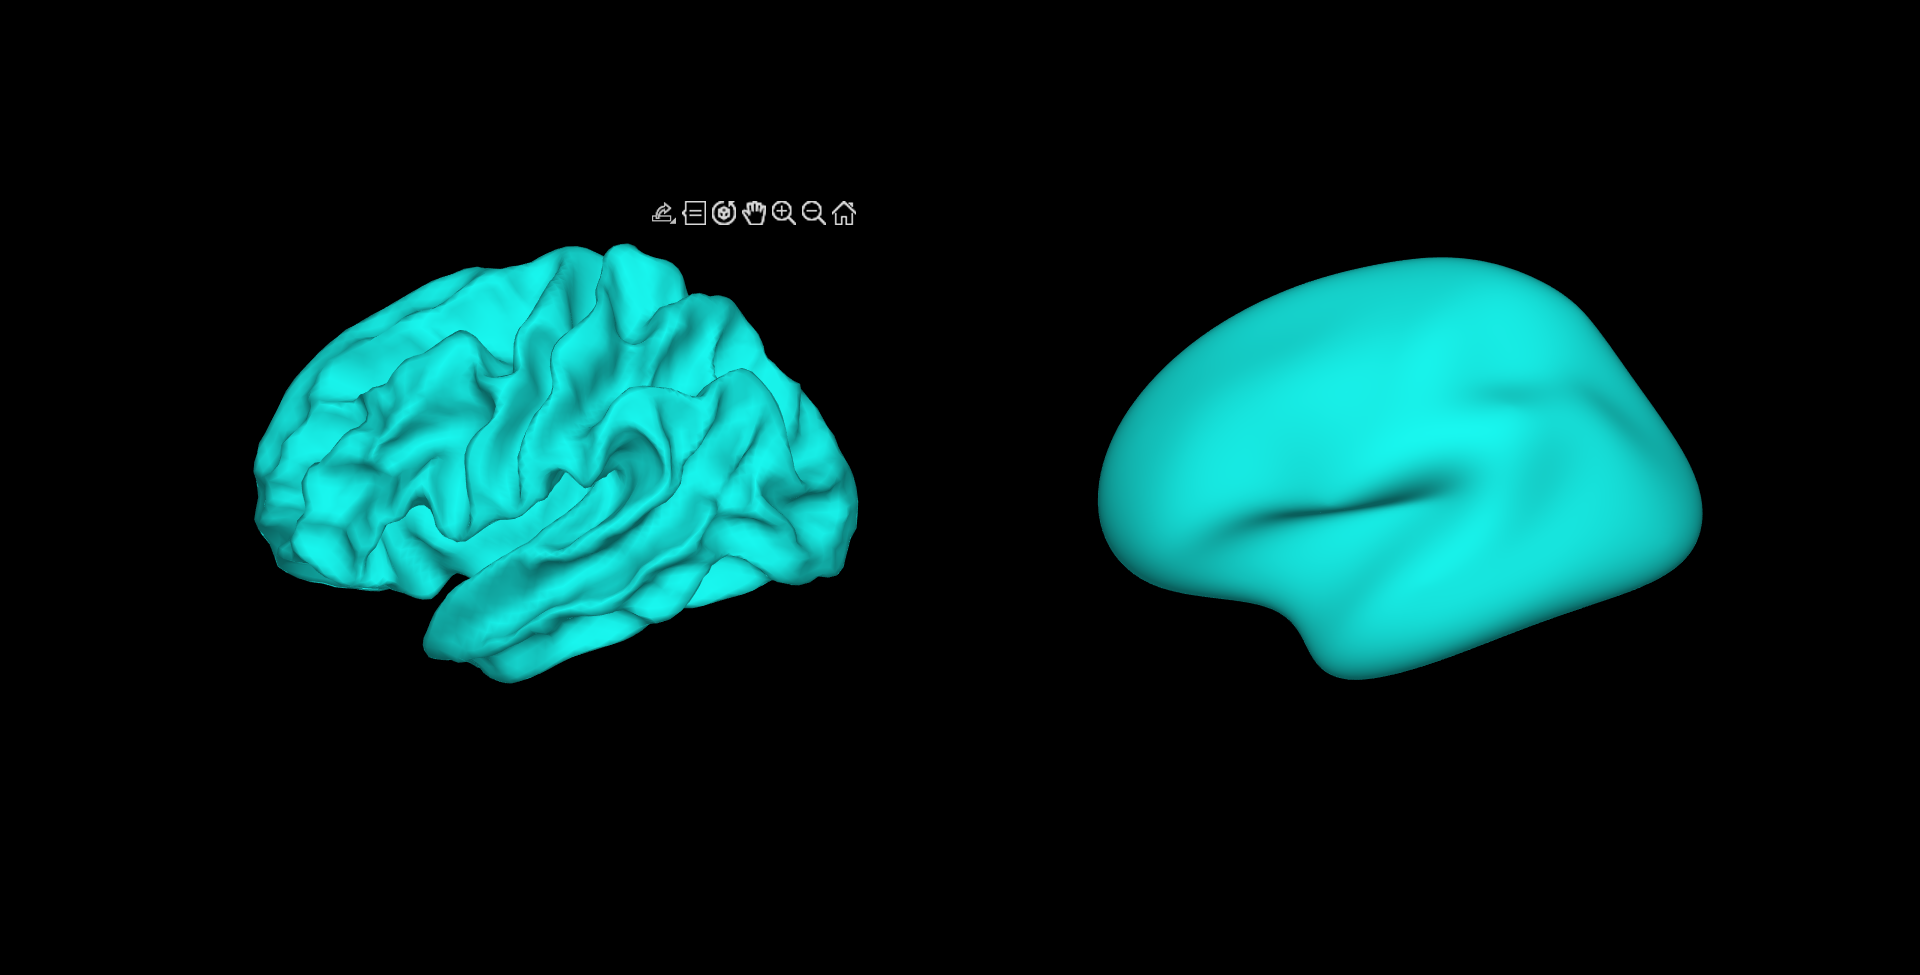

figure; set(gcf,'Visible','on')
subplot(1,2,1)
srfplot(srfwhite.lh, ones(srfwhite.lh.nvertices,1))
subplot(1,2,2)
srfplot(srfinflated.lh, ones(srfwhite.lh.nvertices,1))

## Smoothing surfaces

figure; set(gcf,'Visible','on')
srf = loadsrf;
clear data
data.lh = randn(srf.lh.nvertices, 1);
data.rh = randn(srf.rh.nvertices, 1);
FWHM = 15;
smooth_data = smooth_surface(srf, data, FWHM);
subplot(1,2,1)
srfplot(srf.lh, smooth_data.lh)
subplot(1,2,2)
srfplot(srf.lh, smooth_data.lh, 1)

## Studying the HCP working memory data

sb_dir = statbrainz_maindir;
path4gifti_L = [sb_dir, '\BrainImages\Gifti_files\S1200.L.inflated_MSMAll.32k_fs_LR.surf.gii'];
path4gifti_R = [sb_dir, '\BrainImages\Gifti_files\S1200.R.inflated_MSMAll.32k_fs_LR.surf.gii'];
hcp_srf = gifti2surf(path4gifti_L, path4gifti_R);
load([sb_dir,'BrainImages\Real_data\hcpWM_surface.mat'])

Plot the mean

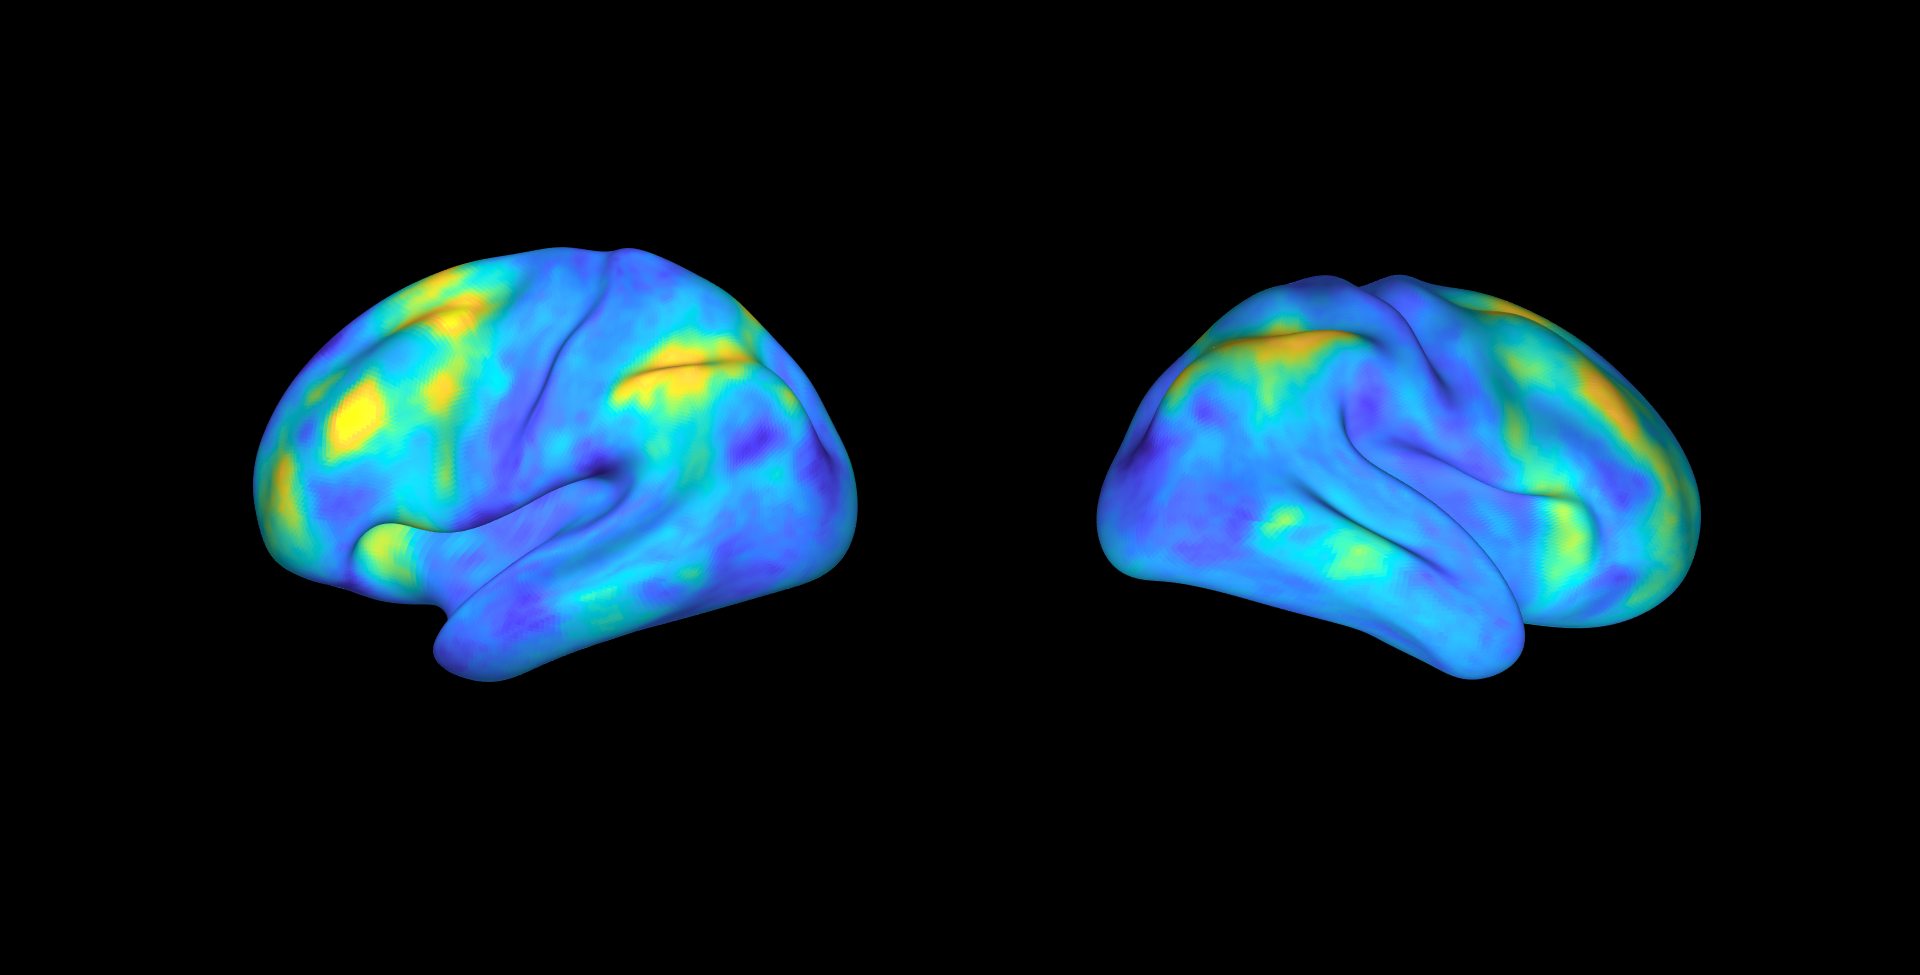

figure; set(gcf,'Visible','on')
subplot(1,2,1)
srfplot(hcp_srf.lh, hcp_data_mean.lh)
subplot(1,2,2)
srfplot(hcp_srf.rh, hcp_data_mean.rh, 1)

Plot the standard deviation

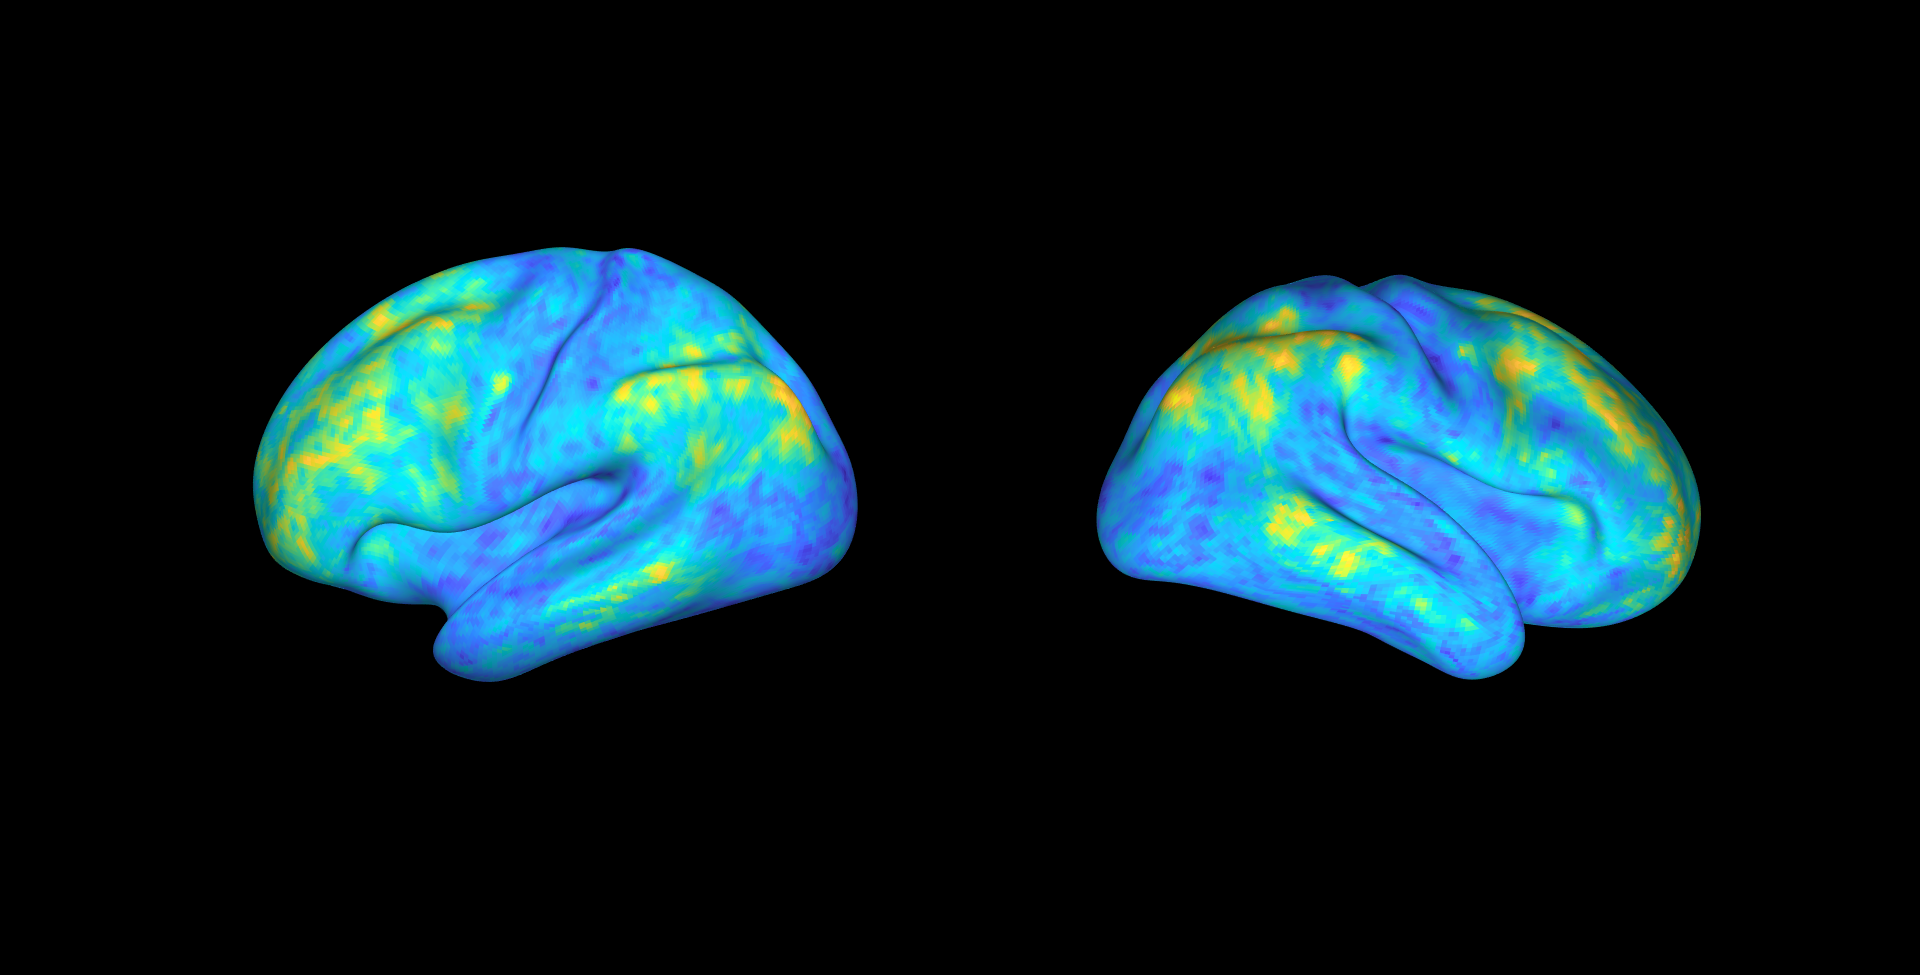

figure; set(gcf,'Visible','on')
subplot(1,2,1)
srfplot(hcp_srf.lh, hcp_data_std.lh)
subplot(1,2,2)
srfplot(hcp_srf.rh, hcp_data_std.rh, 1)

Plot the standard deviation

figure; set(gcf,'Visible','on')
subplot(1,2,1)

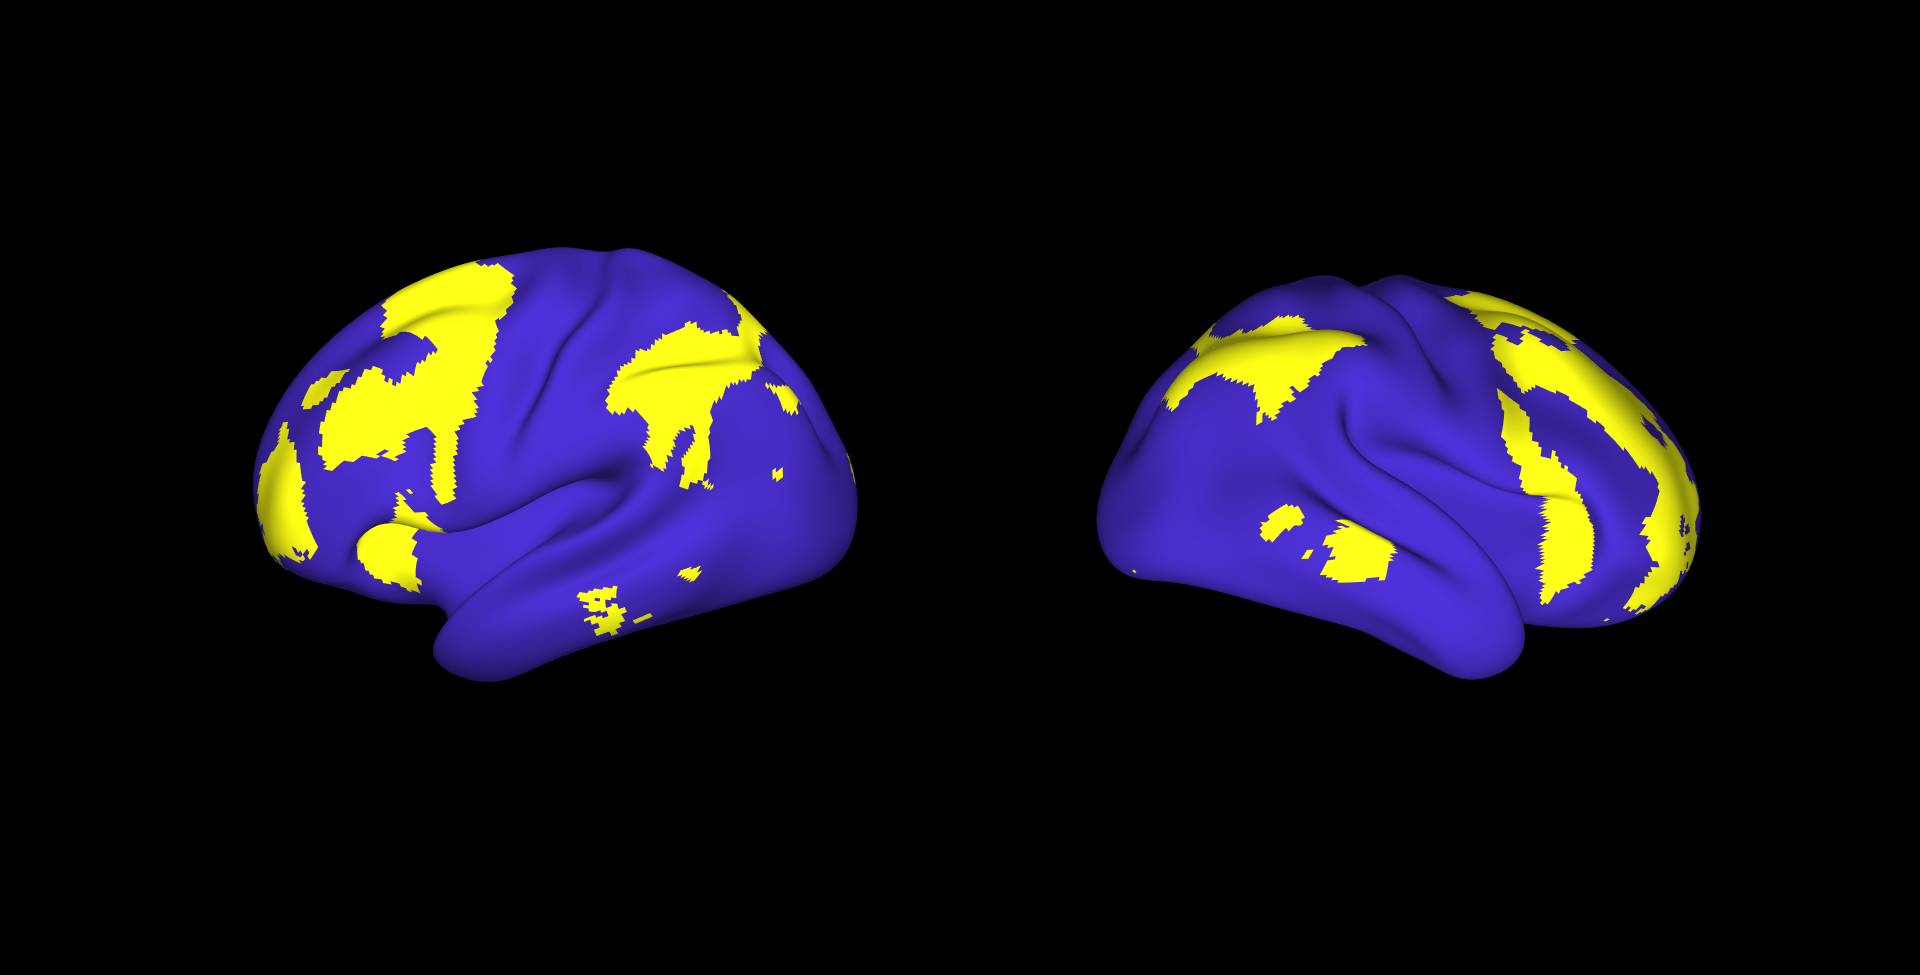

srfplot(hcp_srf.lh, sqrt(78)*hcp_data_mean.lh./hcp_data_std.lh > 3)
subplot(1,2,2)
srfplot(hcp_srf.rh, sqrt(78)*hcp_data_mean.rh./hcp_data_std.rh > 3, 1)

Try plotting the tstatistic and p-value images which are calculated below.

clear tstats pval_im
tstats.lh = sqrt(78)*hcp_data_mean.lh./hcp_data_std.lh;
tstats.rh = sqrt(78)*hcp_data_mean.rh./hcp_data_std.rh;
pval_im.lh = tstat2pval(tstats.lh , 78-1, 0)

pval_im = struct with fields:
    lh: [32492×1 double]

pval_im.rh = tstat2pval(tstats.lh , 78-1, 0)

pval_im = struct with fields:
    lh: [32492×1 double]
    rh: [32492×1 double]

Run BH

figure; set(gcf,'Visible','on')
all_tstats = [tstats.lh, tstats.rh];
medial_wall_mask = isnan(all_tstats);
all_pvals = [pval_im.lh, pval_im.rh];
non_medial_pvals = all_pvals(~medial_wall_mask)

non_medial_pvals =     1.0000
    0.9983
    0.0100
    0.5839
    0.8859
    0.0000
    0.0000
    0.9923
    0.7762
    1.0000


rejection_ind = fdrBH( non_medial_pvals, 0.05 );
sum(rejection_ind)

ans = 13297

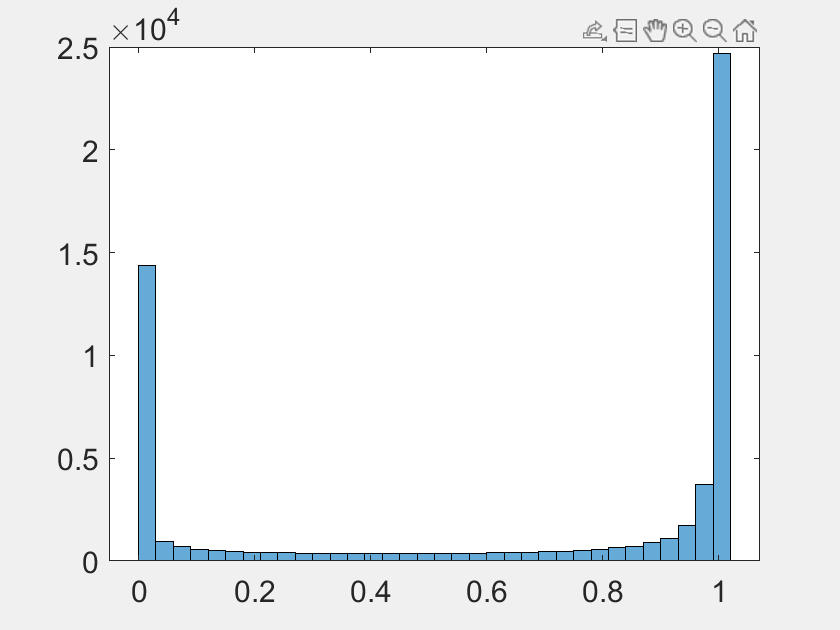

histogram(pvals)

Plot the surviving voxels

figure; set(gcf,'Visible','on')
bh_threshold = max(non_medial_pvals(rejection_ind))

bh_threshold = 0.0112

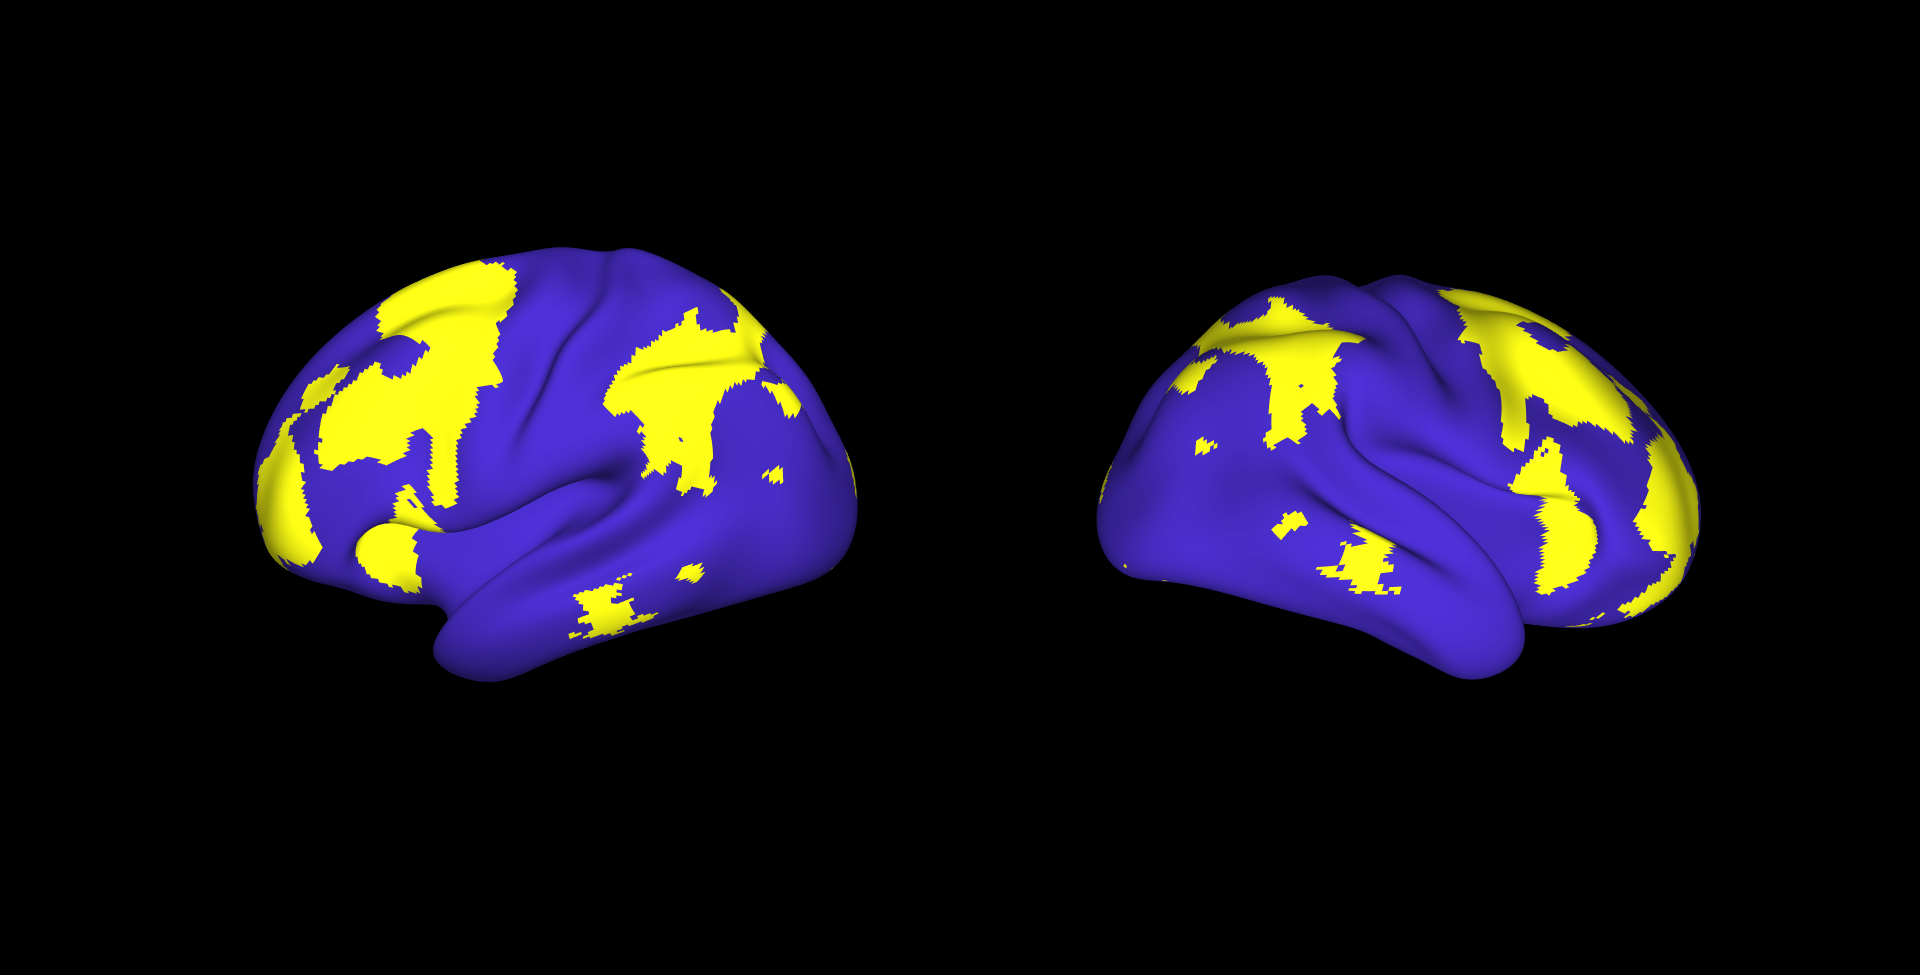

subplot(1,2,1)
srfplot(hcp_srf.lh, pval_im.lh < bh_threshold)
subplot(1,2,2)
srfplot(hcp_srf.rh, pval_im.rh < bh_threshold, 1)

As an exercise consider two sided p-values (an option in the function tstat2pval) and see how the results change.

## Spin Test

srf = loadsrf('fs4', 'sphere')

srf = struct with fields:
    lh: [1×1 struct]
    rh: [1×1 struct]

FWHM = 4;
X = srf_noise(srf, FWHM);
Y = srf_noise(srf, FWHM);

tic
[threhsold, rho_store] = spintest( X, Y, srf, 1000, 0.05, 1 );

-------------------------------------------------------
spin_surface progress:  24.1


toc
figure; set(gcf,'Visible','on')
histogram(rho_store)

rho_store(1)

Explore ways to make X and Y correlated and see if the spin-test picks this up!